clc; 
clear; 

% Specifications
fs = 4000;        % sampling freq (Hz)
T = 1;            % seconds
N = fs * T;       % number of samples
N_TAPS = 4;       % Filter order
step_size = 0.02; % LMS step size (learning rate)

n = (0:N-1)';     % Sample index
t = n/fs;

% Signals 
% Clean Signal
s = 0.6*sin(2*pi*100*t);

% Noise Signal 
rng(0);          % for reproducibility
noise_d = 0.3 * randn(N,1); % noise added to signal
b = [0.5, 0.3, 0.2];
n_p = filter(b, 1, noise_d);
n_p = n_p * 1.2;

% Primary Signal
% scale(normalize) to [-1,1] range
d = s + noise_d;
A_max = max(abs(d));
if A_max > 1
    d = d / A_max;
    s = s / A_max;
    noise_d = noise_d / A_max;
end

noise = n_p / max(max(abs(n_p)), 1);

## LMS Filter

w = zeros(N_TAPS,1);   % Filter weights initialization
x = zeros(N_TAPS,1);   % Reference signal buffer
y = zeros(N,1);   % Filter output
e = zeros(N,1);   % Error signal

for k = 1:N
    x = [noise(k); x(1:end-1)];   % Update reference signal buffer
    y(k) = w.' * x;               % Filter output
    e(k) = d(k) - y(k);           % Error (desired - output)
    w = w + step_size * e(k) * x;   % LMS weight update
end


## Results

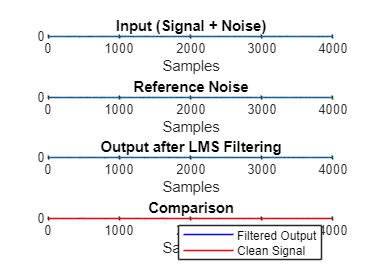

figure;
subplot(4,1,1);
plot(n, d); title('Input (Signal + Noise)'); 
xlabel('Samples'); ylabel('Amplitude');

subplot(4,1,2);
plot(n, noise); title('Reference Noise'); 
xlabel('Samples'); ylabel('Amplitude');

subplot(4,1,3);
plot(n, e); title('Output after LMS Filtering'); 
xlabel('Samples'); ylabel('Amplitude');

subplot(4,1,4);
plot(n, e, 'b', n, s, 'r');
legend('Filtered Output', 'Clean Signal');
title('Comparison'); 
xlabel('Samples'); ylabel('Amplitude');

## Hardware Behavioral Simulation 

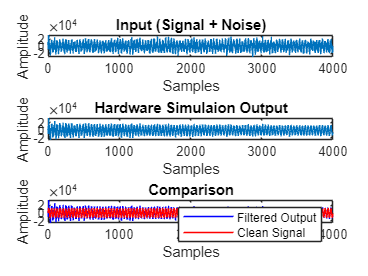

% Quantize 
d_q15 = quantize_15(d);     
n_q15 = quantize_15(noise);
s_q15 = quantize_15(s);
step_size_q15 = quantize_15(step_size);


[e1, w1, x1, y1] = lms_filter_hardware_sim( ...
    d_q15, n_q15, N_TAPS, step_size_q15);

figure;
subplot(3,1,1);
plot(n, d_q15); title('Input (Signal + Noise)'); 
xlabel('Samples'); ylabel('Amplitude');

subplot(3,1,2);
plot(n, e1); title('Hardware Simulaion Output'); 
xlabel('Samples'); ylabel('Amplitude');

subplot(3,1,3);
plot(n, e1, 'b', n, s_q15, 'r');
legend('Filtered Output', 'Clean Signal');
title('Comparison'); 
xlabel('Samples'); ylabel('Amplitude');

## Output Test Vectors

% Output Vectors
fileID = fopen('..\test_vector\testvector.txt', 'w');

% Write data in Q1.15 format
for i = 1:4000
    fprintf(fileID, '%d %d %d\n', d_q15(i), n_q15(i), e1(i));
end

fclose(fileID);
disp('File written successfully: testvector.txt');

File written successfully: testvector.txt


## Test Vector - 12-bit form

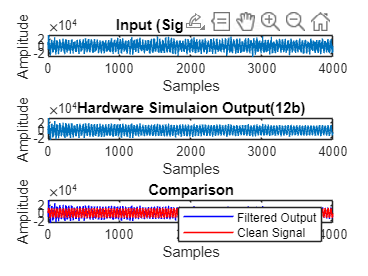

% Q = int16(ADC - 2048) * 16
% ADC = Q / 16 + 2048
d_u12 = bitshift(d_q15, -4, 'int16') + 2048;
n_u12 = bitshift(n_q15, -4, 'int16') + 2048;

d_q15_12 = bitshift((d_u12-2048), 4);
n_q15_12 = bitshift((n_u12-2048), 4);

[e2, w2, x2, y2, delta2] = lms_filter_hardware_sim( ...
    d_q15_12, n_q15_12, N_TAPS, step_size_q15);

figure;
subplot(3,1,1);
plot(n, d_q15); title('Input (Signal + Noise)'); 
xlabel('Samples'); ylabel('Amplitude');

subplot(3,1,2);
plot(n, e2); title('Hardware Simulaion Output(12b)'); 
xlabel('Samples'); ylabel('Amplitude');

subplot(3,1,3);
plot(n, e2, 'b', n, s_q15, 'r');
legend('Filtered Output', 'Clean Signal');
title('Comparison'); 
xlabel('Samples'); ylabel('Amplitude');



% Output Vectors
fileID = fopen('..\test_vector\testvector_ip.txt', 'w');

% Write data in Q1.15 format
for i = 1:30
    fprintf(fileID, '%03X %03X %d\n', d_u12(i), n_u12(i), e2(i));
end

fclose(fileID);
disp('File written successfully: testvector_ip.txt');

File written successfully: testvector_ip.txt


## Output to csv file

d_o = d;
n_o = noise;

writematrix(d_o,'..\test_vector\primary.csv');
writematrix(n_o,'..\test_vector\reference.csv');